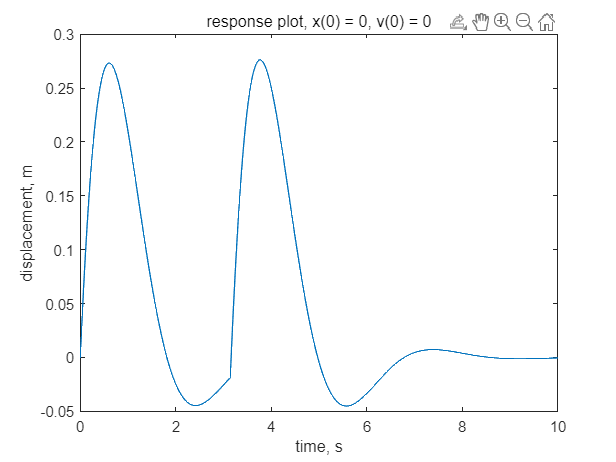

% © 2022 2018100778 최동욱 기계공학과 <ch3044637@khu.ac.kr>
% 임펄스 가진에 대한 해를 계산하고 응답 선도를 표현하라

clear; clc;
m = 1; c = 2; k = 4;
x0 = 0; v0 = 1;
Wn = sqrt(k/m); zeta = c/(2*sqrt(k*m));
Wd = Wn*sqrt(1-zeta^2);
t = 0:0.01:10;

% homogeneous solution
xh = v0/Wd.*exp(-zeta*Wn*t).*sin(Wd*t);
% particular solution
xp = 1/(m*Wd).*exp(-zeta*Wn*(t-pi)).*sin(Wd*(t-pi)).*heaviside(t-pi);

% generous solution
xt = xh + xp;

% plot function
plot(t, xt)
title('response plot, x(0) = 0, v(0) = 0');
xlabel('time, s');
ylabel('displacement, m');